# Define Synth Parameters

addpath(genpath('Test Signals'));

%% Synth 

buffer_length = 480;
fs = 44100;
test_length = 1.0; % in seconds
num_buffs = round((fs*test_length)/buffer_length);
osc = Oscillator(buffer_length,fs);
osc.Freq = 3;


## Sine wave

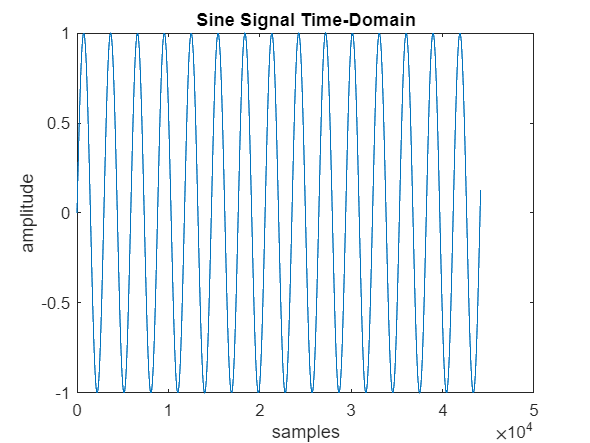

osc.Type = 'Sine';
osc.Detune = 12;
sine_signal = zeros((test_length*fs),1);

for i = 1:num_buffs
    start_ind = ((i-1)*buffer_length)+1;
    end_ind = start_ind + (buffer_length-1);
    [sine_signal(start_ind:end_ind), osc] = process(osc);
end

figure(1);
plot(sine_signal);
title('Sine Signal Time-Domain');
xlabel('samples');
ylabel('amplitude');

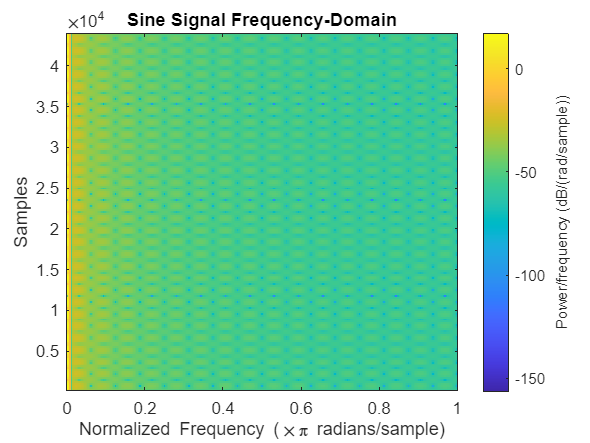



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(2);
spectrogram(sine_signal, hamming(win_length), overlap_length, nfft);
title('Sine Signal Frequency-Domain');

## Square Wave

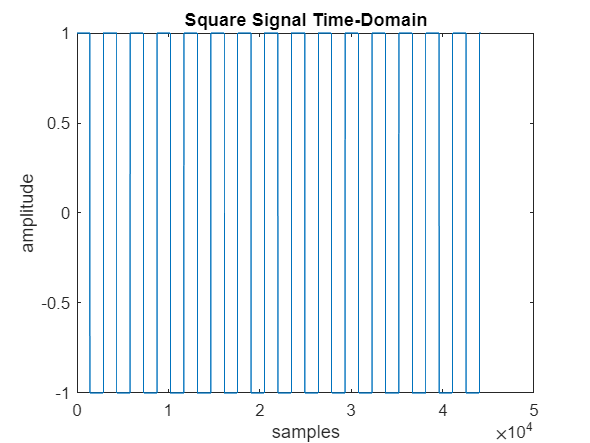

osc.Type = 'Square';
square_signal = zeros((test_length*fs),1);

for i = 1:num_buffs
    start_ind = ((i-1)*buffer_length)+1;
    end_ind = start_ind + (buffer_length-1);
    [square_signal(start_ind:end_ind), osc] = process(osc);
end

figure(3);
plot(square_signal);
title('Square Signal Time-Domain');
xlabel('samples');
ylabel('amplitude');

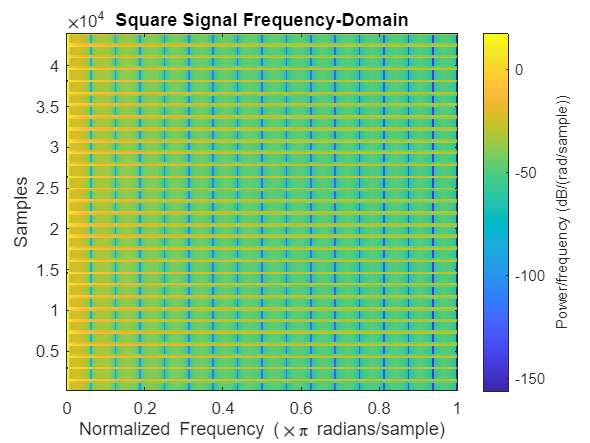



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(4);
spectrogram(square_signal, hamming(win_length), overlap_length, nfft);
title('Square Signal Frequency-Domain');

## Triangle Wave

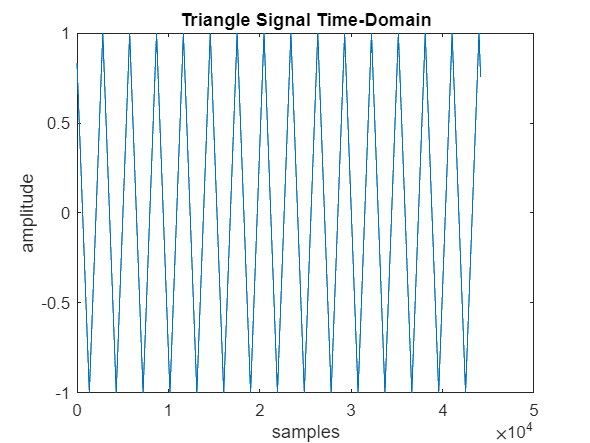

osc.Type = 'Triangle';
triangle_signal = zeros((test_length*fs),1);

for i = 1:num_buffs
    start_ind = ((i-1)*buffer_length)+1;
    end_ind = start_ind + (buffer_length-1);
    [triangle_signal(start_ind:end_ind), osc] = process(osc);
end

figure(5);
plot(triangle_signal);
title('Triangle Signal Time-Domain');
xlabel('samples');
ylabel('amplitude');

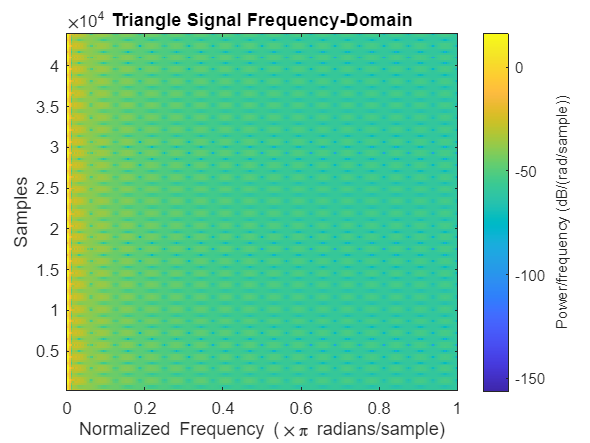



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(6);
spectrogram(triangle_signal, hamming(win_length), overlap_length, nfft);
title('Triangle Signal Frequency-Domain');

## Sawtooth Wave

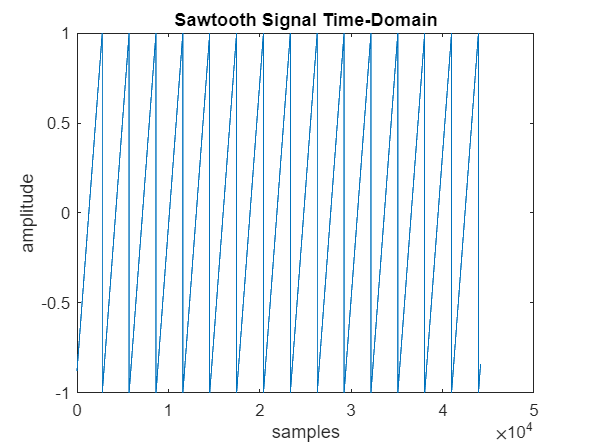

osc.Type = 'Sawtooth';
sawtooth_signal = zeros((test_length*fs),1);

for i = 1:num_buffs
    start_ind = ((i-1)*buffer_length)+1;
    end_ind = start_ind + (buffer_length-1);
    [sawtooth_signal(start_ind:end_ind), osc] = process(osc);
end

figure(7);
plot(sawtooth_signal);
title('Sawtooth Signal Time-Domain');
xlabel('samples');
ylabel('amplitude');

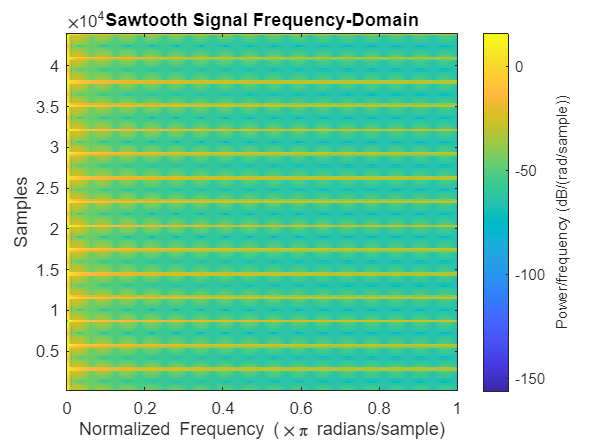

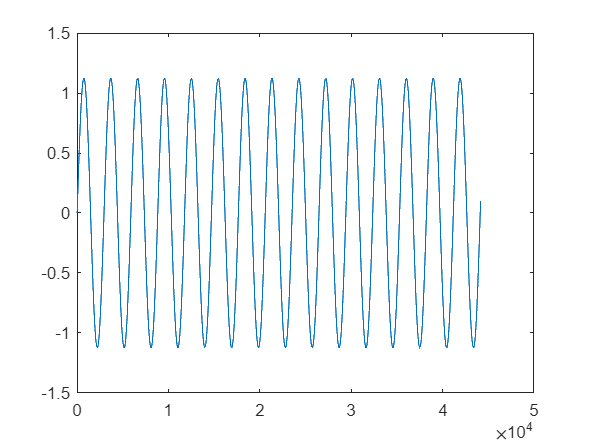



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(8);
spectrogram(sawtooth_signal, hamming(win_length), overlap_length, nfft);
title('Sawtooth Signal Frequency-Domain');